[audio_sig, fs] = audioread("Kanmani Anbodu - Whistle _ Instrumental.mp3");

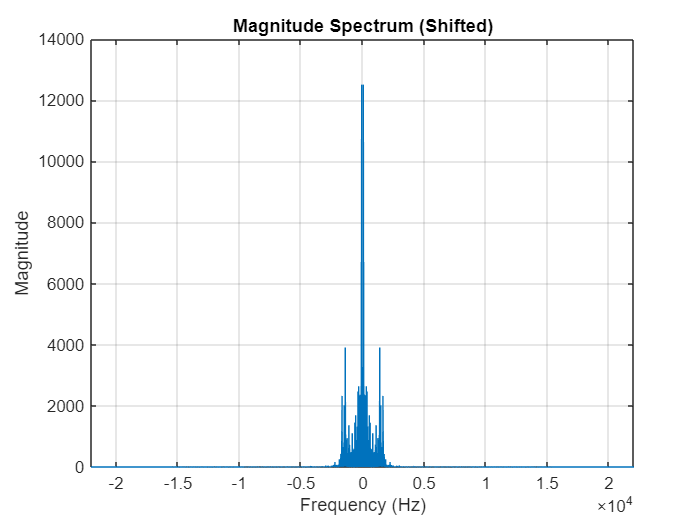

sound(audio_sig, fs);

% upsample
upsampled_sig = upsample(audio_sig,3)

upsampled_sig =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


sound(upsampled_sig, 3*fs);

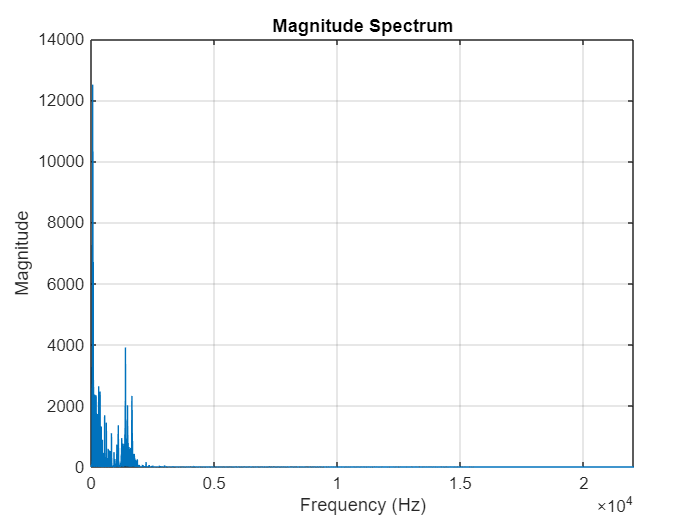

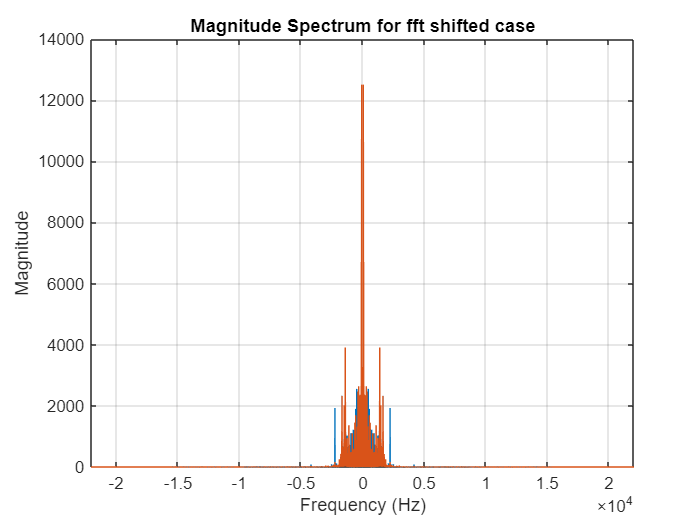

%plot the fft and fft shifted signals for original signal
myFFtFunction(audio_sig, fs, true, true)

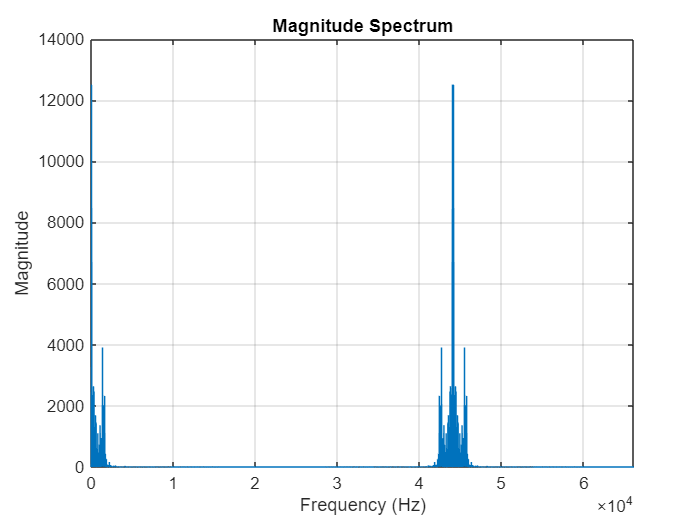

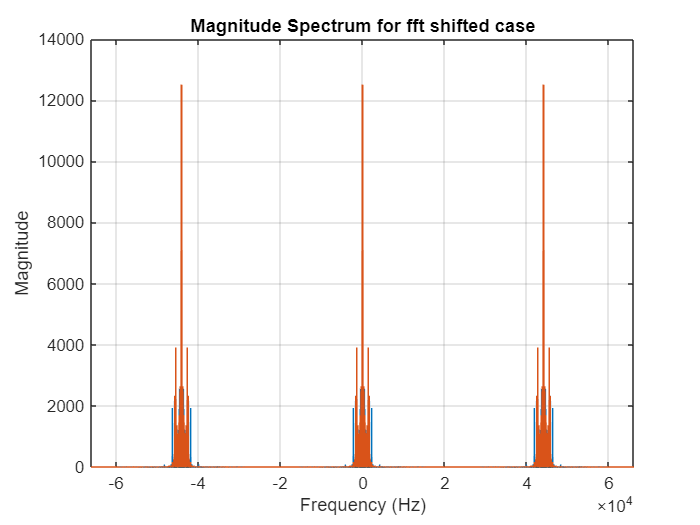

%plot the upsampled signal
myFFtFunction(upsampled_sig, 3*fs, true, true)

downsampled_sig = downsample(audio_sig,3)

downsampled_sig =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


sound(downsampled_sig, fs/3);

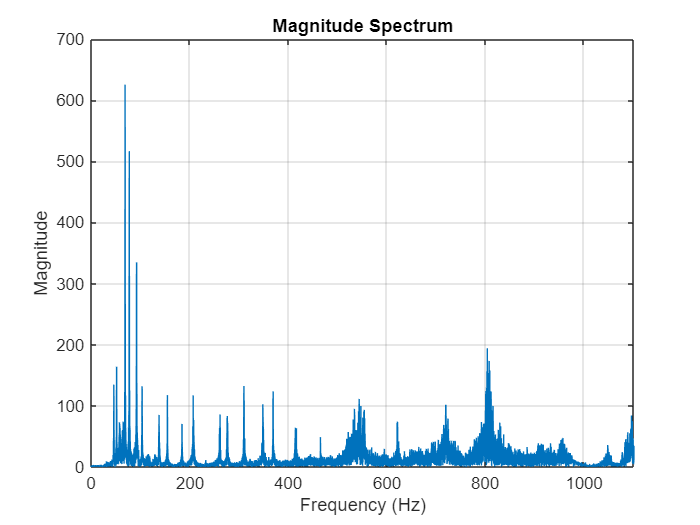

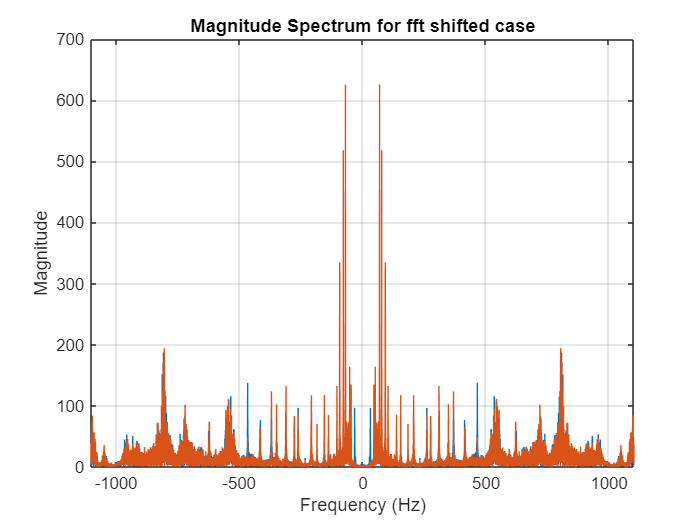

%plot the downsampled signal
alpha = 20;
downsampled_sig = downsample(audio_sig,alpha);
sound(downsampled_sig, fs/alpha);
myFFtFunction(downsampled_sig, fs/alpha, true, true);